filename="meas5.wav";
SDR=audioread(filename);
info = audioinfo(filename)

info = struct with fields:
             Filename: 'C:\Users\Wout\OneDrive - Universiteit Antwerpen\Documenten\Master\1 MAP\Simulation\SNR\Precise SNR FFT\meas5.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 2
           SampleRate: 1000000
         TotalSamples: 136860000
             Duration: 136.8600
                Title: '137.55 MHz, BW 1 MHz, 2023-02-23 12:58'
              Comment: 'Created by DESKTOP-3EC4Q02\Wout on 2023-02-23 12:58:36, filename C:\Users\Wout\OneDrive - Universiteit Antwerpen\Bureaublad\23-Feb-2023 125836.937 137.550MHz.wav'
               Artist: 'SDR-Radio.com, B210 (A:A)'
        BitsPerSample: 32


The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 100.000000


FFT_power = 1.0e-05 *

    0.0035
    0.0042
    0.0001
    0.0028
    0.0010
    0.0013
    0.0036
    0.0051
    0.0119
    0.0010


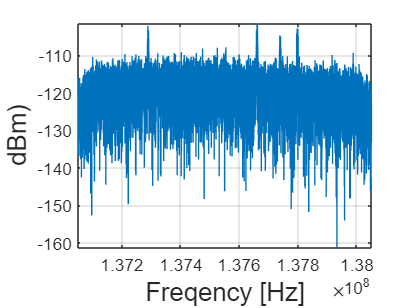

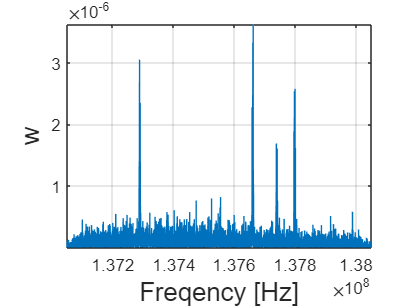

sampleRate= info.SampleRate;
center_freq=137.55E6; %in MHz
seconds=4;
SDR_snippet=SDR(((seconds-1)*1000000:seconds*1000000),:);

IQData = SDR(:,1)+1i*SDR(:,2);

%calculate the fft 
[fft_power, fft_dBm] = Precise_FFT(IQData,1,1*sampleRate,sampleRate,center_freq);

[noise_level_dBm,signal_level_dBm,snr]=SNR_V2(fft_power,sampleRate,center_freq,center_freq+57300,center_freq+160000)

binsizefft = 100

lowest_bin_freq = 137050000

This is an ORBCOMM channel


noise_level_dBm = -103.7216

signal_level_dBm = -93.2248

snr = 10.4968


[ORBCOMM,low_freq,high_freq,number] = get_channel_info(137.2875E6)

This is an ORBCOMM channel


ORBCOMM = logical
   1


low_freq = 137287500

high_freq = 137290000

number = 115